# Practice NODC Cast work

% Load Data
cd('C:\Users\ajs82292\Desktop\Research\Matlab\Source')
load("02cleanNODC.mat")

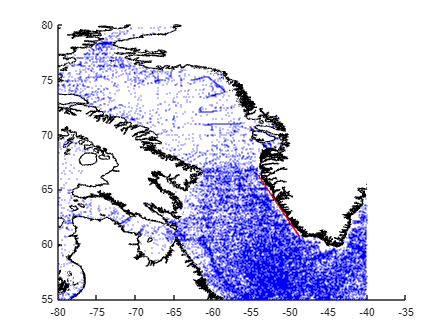

% Work on simplified coastline (ginput) (Needs to have better coast
% selection)
clf
hold on
plot(cx,cy,'k')
xlim([-80,-35])
ylim([55,80])
% Already selected coastline points
run = 2 ;
for i = 1:1:1
    if run == i 
        SWgcoast = ginput(2);
        save ("SWgcoast.mat", "SWgcoast");
    end
end
load('SWgcoast.mat')
scatter(lon,lat,1,'MarkerFaceColor','b','MarkerEdgeAlpha','0') ;
plot (SWgcoast(:,1),SWgcoast(:,2) ,'r')
hold off

% Creation of Parallelograms on SW Coast
m = ((SWgcoast(2,2)-SWgcoast(1,2))/(SWgcoast(2,1)-SWgcoast(1,1))) ; %slope of simplified coastline
recwidth = 10*2 ; % km doubled as it is 10 "radius" Change value for different sized cast boxes
reclength = 20*2 ; % km doubled as it is 20 "radius" Change value for different sized cast boxes
width_2 = recwidth/2 ; % for dynamic plot titles
length_2 = reclength/2 ; % for dynamic plot titles
recwidth_coast = 10*2 ; % do not change, for defining larger polygon
reclength_coast = 20*2 ; % do not change, for defining larger polygon
y_SWcoast = [SWgcoast(2,2),SWgcoast(1,2)] ; 
x_SWcoast = [SWgcoast(2,1), SWgcoast(1,1)] ; 
dx = SWgcoast(2,2) - SWgcoast(1,2) ;
dy = SWgcoast(2,1) - SWgcoast(1,1) ;
lengthdeg = km2deg(reclength) ;
widthdeg_lon = 111.320 .*cosd(lat) ;
widthdeg_lon = recwidth./widthdeg_lon ;
widthdeg_coast = recwidth_coast./widthdeg_lon ; % For larger polygon
lengthdeg_coast = km2deg(reclength_coast) ;% For larger polygon
SWwidthdeg = 111.320* cosd(y_SWcoast) ;
SWwidthdeg = recwidth./SWwidthdeg ;
SWwidthdeg_coast = 111.320* cosd(y_SWcoast) ;
SWwidthdeg_coast = recwidth_coast./SWwidthdeg_coast ;

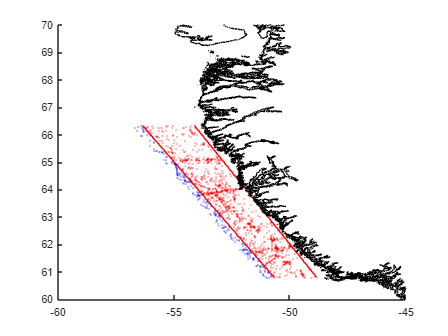

% Find Casts within defined area
x5_SWcoast = x_SWcoast - 5*SWwidthdeg_coast ; % This should not change
extendecoast = x5_SWcoast - SWwidthdeg; % This will change depending on size of cast boxes
SW_xcombined = [x5_SWcoast,flip(x_SWcoast)] ; % counterclockwise verticies order
SW_ycombined = [y_SWcoast,flip(y_SWcoast)] ; % counterclockwise verticies order
SW_xcombined_coast = [extendecoast,flip(x_SWcoast)] ;
SWidx= inpolygon(lon,lat, SW_xcombined,SW_ycombined) ; %idx of core coastal area
SWidx_coast = inpolygon(lon,lat, SW_xcombined_coast,SW_ycombined) ; % idx of extended area
% Isolate SW variables needs to include 50km+ width casts 
SW_lon = lon(SWidx) ;
SW_lat = lat(SWidx) ;
SW_lon_coast = lon(SWidx_coast) ;
SW_lat_coast = lat(SWidx_coast) ;
SW_watdep_coast = watdep(SWidx_coast);
SW_sal_coast = sal(SWidx_coast);
SW_temp_coast = temp(SWidx_coast);
SW_dep_coast = dep(SWidx_coast) ;
SW_yea_coast = yea(SWidx_coast);
SW_day_coast = day(SWidx_coast);
SW_mon_coast = mon(SWidx_coast);
SW_widthdeg = widthdeg_lon(SWidx) ; 
%Plot
clf
hold on 
plot(x_SWcoast,y_SWcoast, 'r')
plot(x5_SWcoast,y_SWcoast,'r')
plot(cx,cy, 'k')
xlim([-60,-45])
ylim([60,70])
scatter(SW_lon_coast,SW_lat_coast,1,'MarkerFaceColor','b','MarkerEdgeAlpha','0') ;
scatter(SW_lon,SW_lat,1,'MarkerFaceColor','r','MarkerEdgeAlpha','0') ;
hold off

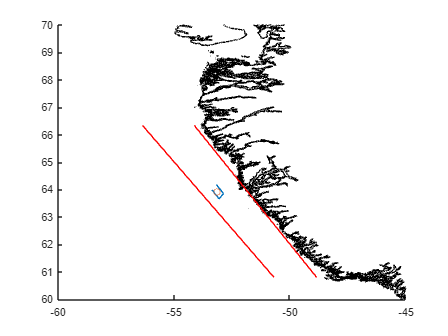

% Defining parallelogram verticies for casts (length and width not correct)
lengthrad = deg2rad(lengthdeg) ;
lengthdeg = ones(1,length(SW_widthdeg)).*lengthdeg ;
widthrad = deg2rad(SW_widthdeg) ;
half_length = lengthdeg./1.6 ; % mess with the divisibles to get the km right (this is within 1 km after limited testing)
half_width = SW_widthdeg./3; %  mess with the divisibles to get the km right (this is within 1 km after limited testing)
for i = 1:numel(SW_lon)
    % Calculate the coordinates of the vertices
    vertex1 = [SW_lon(i) - half_width; SW_lat(i) + half_length]; %careful, longitude is negative so watch signs
    vertex2 = [SW_lon(i) - half_width; SW_lat(i) - half_length];
    vertex3 = [SW_lon(i) + half_width; SW_lat(i) - half_length];
    vertex4 = [SW_lon(i) + half_width; SW_lat(i) + half_length];
    % Arrange vertices in counterclockwise order
    vertices = [vertex1(:,i), vertex2(:,i), vertex3(:,i), vertex4(:,i)];
    % Store in cell array
    vertices_cell{i} = vertices;
end
% Rotate Verticies to allign with angle to coast
SW_angle = atan2d(dx,dy) ; % degrees
bearing = SW_angle - 90 ; % find angle in relation to y-axis
R = [cosd(bearing), -sind(bearing); sind(bearing), cosd(bearing)];
for i = 1:length(vertices_cell)
center_x = vertices_cell{i}(1,:) - SW_lon(i);
center_y = vertices_cell{i}(2,:) - SW_lat(i);
SW_rotated = R * [center_x;center_y] ;
SW_rotated_cell{i} = SW_rotated ;
SW_xrotated = SW_rotated_cell{i}(1,:) + SW_lon(i) ;
SW_yrotated = SW_rotated_cell{i}(2,:) + SW_lat(i) ;
SW_xrotatedcell{i} = SW_xrotated ;
SW_yrotatedcell{i} = SW_yrotated ;
SW_rotated_verticies = [SW_xrotatedcell{i};SW_yrotatedcell{i}] ;
SW_rotvertcell{i} = SW_rotated_verticies ;
end
clear('SW_rotated_verticies')
clear('SW_yrotated')
clear('SW_xrotated')
clear('SW_rotated_cell')
clear('SW_yrotated')
clear('SW_xrotated')
clear('SW_yrotatedcell')
clear('SW_xrotatedcell')
clear('SW_rotated_cell')
clear('SW_rotated')
%Plot Angled Rectangles
clf
hold on
plot(SW_rotvertcell{1}(1,:),SW_rotvertcell{1}(2,:) )
scatter(SW_lon(1,1),SW_lat(1,1))
plot(cx,cy,' k')
xlim([-60,-45])
ylim([60,70])
plot(x_SWcoast,y_SWcoast, 'r')
plot(x5_SWcoast,y_SWcoast,'r')
hold off

% Clear Unneeded variables
clear('vertex1')
clear('vertex2')
clear('vertex3')
clear('vertex4')
clear('R')
% Rectangle Calculations
% Interpolate every 1 m for the SW coastal region
max_length = max(cellfun(@numel,SW_dep_coast)) ;
DepInterval = (0:1:max_length)';
int_temp = {} ;
run = 2 ; % will rerun interpolated, temp and salinity as well as cast box indicies
for i = 1:1:length(SW_dep_coast)
    if run == 1 
        SW_int_temp{1,i} = interp1(SW_dep_coast{1,i},SW_temp_coast{1,i}, DepInterval, 'linear') ;
    end
end
for i = 1:1
    if run == 1
save ("SW_int_temp.mat", "SW_int_temp");
    end
end
    load('SW_int_temp.mat')
%Salinity 
int_sal = {} ;
for i = 1:1:length(SW_dep_coast)
   if run == 1
    SW_int_sal{1,i} = interp1(SW_dep_coast{1,i},SW_sal_coast{1,i}, DepInterval, 'linear') ;
   end
end
for i = 1:1
    if run == 1
 save ("SW_int_sal.mat", "SW_int_sal");
    end
end
load('SW_int_sal.mat')
% Create 15 day indicies regardless of year 
SW_date = ([SW_yea_coast; SW_mon_coast; SW_day_coast]) ;
SW_date(4,:) = datenum(0,SW_date(2,:),SW_date(3,:));% everything set in the year 0 to make for easy sorting by day and month
SW_datenum = datenum(0,SW_date(2,:),SW_date(3,:)) ;% everything set in the year 0 to make for easy sorting by day and month
day_range = 3 ; % adjust this as needed, actual day range is 2*number listed
day_range_2 = day_range*2 ; % For dynamic naming
middle_idx = SW_date(4,:) >= day_range & SW_date(4,:) <= 365-day_range;
earlyjan_idx = (SW_date(4,:) < day_range) ; % only includes earliest part of Jan that overlaps with interval 
latedec_idx = (SW_date(4,:) > 365-day_range); % only includes latest part of Dec that overlaps with interval 
Jan_range = 365-day_range + (SW_datenum(earlyjan_idx) ); % Earliest Day to include
Jan_range(2,:) = SW_datenum(earlyjan_idx)+day_range ; % Latest Day to include
Middle_range = SW_datenum(middle_idx)- day_range ;
Middle_range(2,:) = SW_datenum(middle_idx)+ day_range ;
Dec_range = SW_datenum(latedec_idx)- day_range ;
Dec_range(2,:) = SW_datenum(latedec_idx)-365+day_range;
SW_ranges = [Jan_range,Middle_range,Dec_range] ;
clear('middle_idx')
clear('earlyjan_idx')
clear('latedec_idx')
% Create indicies for individual rectangles 
SW_poly_idxcell = cell(length(SW_lon_coast), 1); % preallocate
for i = 1:length(SW_rotvertcell)
    for j = 1:length(SW_lon_coast)
        if run == 1 ;
            SW_poly_idx = inpolygon(SW_lon_coast,SW_lat_coast,SW_rotvertcell{i}(1,:),SW_rotvertcell{i}(2,:)) ; % extended area +core casts that fall into core cast boxes
SW_poly_idxcell{j} = SW_poly_idx ;
    end
    end
end
for i = 1:1
    if run == 1
 save("SW_poly_idx.mat",'SW_poly_idxcell')
    end
end
    load('SW_poly_idx.mat')
clear('SW_poly_idx')
% Create indicies for dates
jan_idx = false(1,length(SW_ranges)) ;
Middle_idx = false(1,length(SW_ranges)) ;
dec_idx = false(1,length(SW_ranges)) ;
% Overlapping January Dates
for i = 1:length(SW_ranges)
    for j = 1:length(Jan_range)
    if SW_datenum(i) >= Jan_range(1,j) | SW_datenum(i) <= Jan_range(2,j)
        jan_idx(i) = 1 ;
        Jan_cell{j} = jan_idx ;
    end
    end
end
% Middle Dates
for i = 1:length(SW_ranges)
    for j = 1:length(Middle_range)
    if SW_datenum(i) >= Middle_range(1,j) & SW_datenum(i) <= Middle_range(2,j)
Middle_idx(i) = 1;
Middle{j} = Middle_idx ;
    end
    end
end
% Overlapping Dec Dates
for i = 1:length(SW_ranges)
    for j = 1:length(Dec_range)
         if SW_datenum(i) >= Dec_range(1,j) | SW_datenum(i) <= Dec_range(2,j)
        dec_idx(i) = 1 ;
       Dec_cell{j} = dec_idx ;
    end
    end
end
% Concatenate Overlapping [Jan,Middle,Dec] cell arrays (Looks Correct but need to test
SW_date_idx_cell =  ([Jan_cell,Middle,Dec_cell]) ;
% Combine Date and Polygon indicies for temp and sal
for i = 1:length(SW_poly_idxcell)
    SW_poly_temp = SW_int_temp(SW_poly_idxcell{i} & SW_date_idx_cell{i}) ;
    SW_poly_temp_cell{i} = SW_poly_temp ;
end
for i = 1:length(SW_poly_idxcell)
    SW_poly_sal = SW_int_sal(SW_poly_idxcell{i} & SW_date_idx_cell{i}) ;
    SW_poly_sal_cell{i} = SW_poly_sal ;
end
% Calculate Means
counts = zeros(1,numel(SW_poly_temp_cell) );
max_length = max(counts) ;
for i = 1:length(SW_poly_sal_cell)
    insidearray = cell2mat(SW_poly_sal_cell{i}) ;
    SW_sal_expanded{1,i} = insidearray ;
end
for i = 1:length(SW_poly_temp_cell)
    insidearray = cell2mat(SW_poly_temp_cell{i}) ;
    SW_temp_expanded{1,i} = insidearray ;
end
% Means 
for i = 1:length(SW_sal_expanded)
    SW_means = mean(SW_sal_expanded{i},2,'omitnan') ;
    SW_sal_means_cell{i} = SW_means ;
end
for i = 1:length(SW_temp_expanded)
    SW_means = mean(SW_temp_expanded{i},2,'omitnan') ;
    SW_temp_means_cell{i} = SW_means ;
end
% Remove unused casts from int_sal and int_temp
not_empty = ~cellfun(@isempty,SW_sal_means_cell) ;
SW_int_sal = SW_int_sal(not_empty) ;
SW_int_temp = SW_int_temp(not_empty) ;
SW_sal_means_cell = SW_sal_means_cell(not_empty) ;
SW_temp_means_cell = SW_temp_means_cell(not_empty) ;
% Calculate Anomalies
for i = 1:length(SW_int_sal)
SW_Anmly = SW_sal_means_cell{i} - SW_int_sal{i} ;
SW_sal_Anmly_cell{i} = SW_Anmly ;
end
for i = 1:length(SW_int_temp)
SW_Anmly = SW_temp_means_cell{i} - SW_int_temp{i} ;
SW_temp_Anmly_cell{i} = SW_Anmly ;
end
clear('Jan_cell')
clear('Jan_idx')
clear('Jan_range')
clear('Dec_cell')
clear('Dec_idx')
clear('Dec_range')
clear('Middle')
clear('Middle_idx')
clear('Middle_range')
clear('SW_poly_temp')
clear('SW_poly_sal')
clear('SW_Anmly')

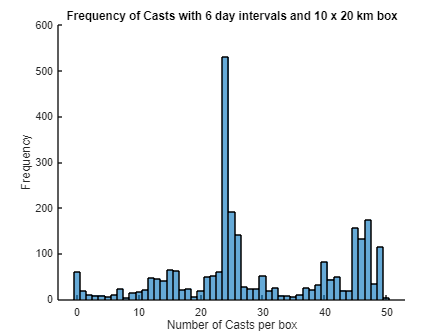

% Statistics
% Frequency of Counts
for i = 1:numel(SW_poly_temp_cell)
    % Get the current cell array
    subCellArray = SW_poly_temp_cell{i};
    % Count the number of elements in the current cell array
    counts(i) = numel(subCellArray);
end
%PlotHistogram (20x10 15 days)
clf
hold on
histogram(counts, 'BinMethod', 'integers');
xlabel('Number of Casts per box');
ylabel('Frequency');
title(sprintf('Frequency of Casts with %d day intervals and %d x %d km box', day_range_2, width_2,length_2))
hold off

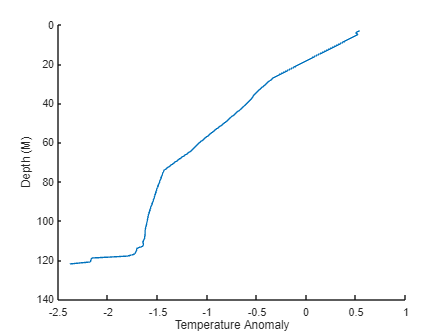

% Plot Example Temperature Anomaly
clf
hold on
plot(SW_temp_Anmly_cell{1,113},DepInterval)
axis ij
xlabel('Temperature Anomaly')
ylabel('Depth (M)')
hold off

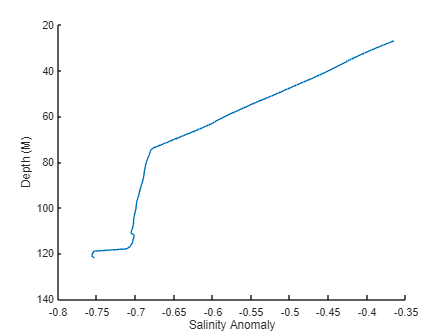

% Plot Example Salinity Anomaly
clf
hold on
plot(SW_sal_Anmly_cell{1,113},DepInterval)
axis ij
xlabel('Salinity Anomaly')
ylabel('Depth (M)')
hold off

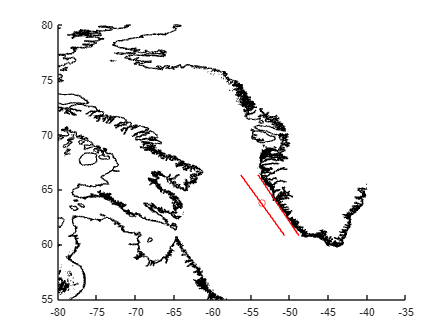

%Plot Example Station
clf
hold on
scatter(SW_lon(113),SW_lat(113), 'r')
xlim([-80,-35])
ylim([55,80])
plot(cx,cy, 'k')
plot(x_SWcoast,y_SWcoast, 'r')
plot(x5_SWcoast,y_SWcoast,'r')
hold off

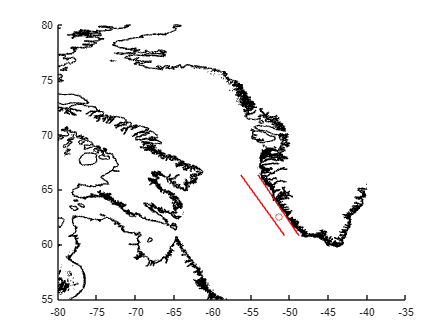

% Plot Example Station 2 (varies with lengthxwidth)
clf
hold on
scatter(SW_lon(1903),SW_lat(1903), 'r')
xlim([-80,-35])
ylim([55,80])
plot(cx,cy, 'k')
plot(x_SWcoast,y_SWcoast, 'r')
plot(x5_SWcoast,y_SWcoast,'r')
hold off

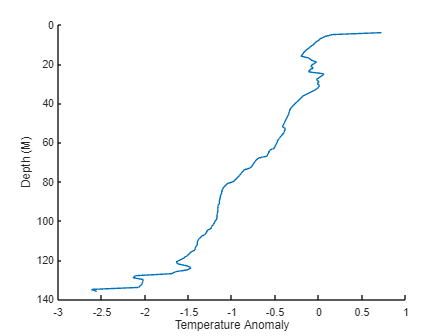

% Plot Example 2 Temperature Anomaly
clf
hold on
plot(SW_temp_Anmly_cell{1,1903},DepInterval)
axis ij
xlabel('Temperature Anomaly')
ylabel('Depth (M)')
hold off

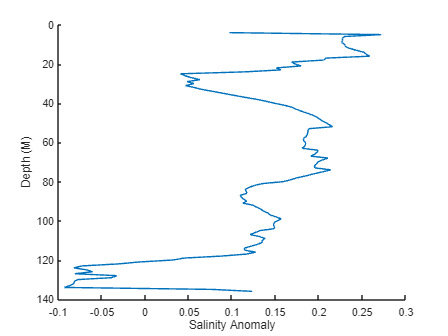

% Plot Example 2 Salinity Anomaly
clf
hold on
plot(SW_sal_Anmly_cell{1,1903},DepInterval)
axis ij
xlabel('Salinity Anomaly')
ylabel('Depth (M)')
hold off